ans =    541     1


ind = 2

    64     1



ind = 3

    64     1



ind = 4

    64     1



ind = 5

    64     1



ind = 6

    64     1



ind = 7

    64     1



ind = 8

    64     1



ind = 9

    64     1



ind = 10

    64     1



ind = 11

    64     1



ind = 12

    64     1



ind = 13

    64     1



ind = 14

    64     1



ind = 15

    64     1



ind = 16

    64     1



ind = 17

    64     1



ind = 18

    64     1



ind = 19

    64     1



ind = 20

    64     1



ind = 21

    64     1



ind = 22

    64     1



ind = 23

    64     1



ind = 24

    64     1



ind = 25

    64     1



ind = 26

    64     1



ind = 27

    64     1



ind = 28

    64     1



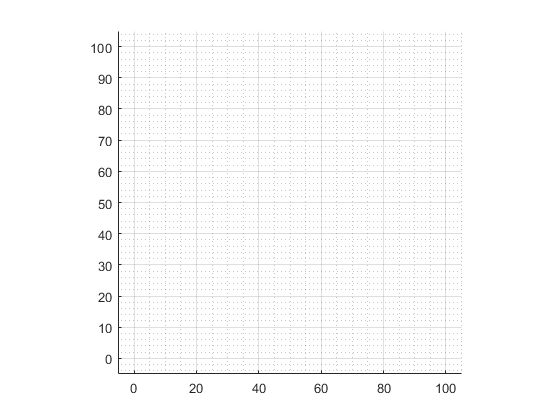

oct(false, 3, 5, 100, 1)

set(gca, 'color', [0 0 0]);

function [x,y,xi,yi] = oct (doPlot,depth, numRotations,interval, gap)
%% Input handling:
if nargin < 1 || isempty(doPlot)
  doPlot = false;
end
%% Initialization:
origin = [0,0];
outerD = 1000;
thetamax = numRotations*(2*pi);
%% Calculation of (x,y) - underlying archimedean spiral. with fixed outer diameter 1000um
hil = hilbert(depth);
width = abs(hil(1)-hil(end));
DST = 2*width+5;
% innerD = outerD-(2*numRotations-1)*interval
innerD = DST;
theta = 0:0.01:thetamax; %resolution
x = (innerD + interval.*theta/(2*pi)).*cos(theta);
y = (innerD + interval.*theta/(2*pi)).*sin(theta);
L = spiralL(numRotations,outerD,innerD);
%% Calculation of equidistant (xi,yi) points on spiral.
% TODO: get DST as a function of the depth of the hilbert curve
hil = hilbert(depth);
width = abs(hil(1)-hil(end));
DST = 2*width+2; 

cRes = 360; 
numSeg = ceil(2*L/DST);
[xi,yi] = deal(NaN(numSeg,1));
%empty list for connection lines
% startX =[];startY = [];
% endX =[];endY = [];idx = 1;
%Start a new figure
figure(); 
%plot(x,y,'b-','linewidth',1);
hold on; axis equal; grid on; grid minor;
hAx = gca; hAx.XLim = [-5 105]; hAx.YLim = [-5 105];
hP = plot(xi,yi); %plot marker
size(xi)
size(yi);
hP.XData(1) = x(end); hP.YData(1) = y(end);
%% keep track of start and end points of hilbert polygon
xPolygonEndPoints = [];
yPolygonEndPoints = [];
xPolygonStartPoints = [];
yPolygonStartPoints = [];

%% calculate the final and current radius
%final radius is equal to furthestRadius - ((numRotations-1)*interval)
currRadius = distance(x(end), y(end));
finalRadius = currRadius - ((numRotations-1)*interval);


%% create a table to store x and y values
x_y_coordinates = [];

%% add hilbert curves until the abs value of the curr radius is less than or equal to the min radius
% for ind = 2:numSeg
ind = 2
while (abs(currRadius) > abs(finalRadius))
  P = InterX([x;y], makeCircle([hP.XData(ind-1),hP.YData(ind-1)],DST/2,cRes));  
  absolute = abs(P(1,:)-origin(1)+1i*(P(2,:)-origin(2)));
  % get the starting point for hilbert
  [~,I] = min(absolute);
  if doPlot, pause(0.1); end
  hP.XData(ind) = P(1,I);
  hP.YData(ind) = P(2,I);

  % create a hilbert curve
  [hilbertX, hilbertY] = hilbert(depth);
  hold on
  
  % draw the polygon
  [xPolygon, yPolygon] = drawPolygon(hilbertX, hilbertY, gap);
%   
  
  % shift hilbert curve and polygon
  shiftX = hP.XData(ind-1);
  shiftY = hP.YData(ind-1);
  [hilbertX, hilbertY] = shiftData(hilbertX, hilbertY, shiftX, shiftY);
  
  %find current intersection point
  curX = hP.XData(ind);
  curY = hP.YData(ind);
  v = [curX-hilbertX(1) curY-hilbertY(1)];
  

  
  %rotate hilbert
  ang = vec_angle(v(1), v(2));
  polyAng = vec_angle(v(1), v(2));
  [hilbertX, hilbertY] = rotxy(hilbertX, hilbertY, ang);
  [xPolygon, yPolygon] = rotxy(xPolygon, yPolygon, polyAng);

  % shift to proper place on spiral
  [hilbertX, hilbertY] = shiftData(hilbertX, hilbertY, shiftX, shiftY);
  [xPolygon, yPolygon] = shiftPolygon(xPolygon, yPolygon, shiftX, shiftY); 
  
  % add the start and end points of the curr polygon
  xPolygonEndPoints = [xPolygonEndPoints, xPolygon(end)];
  yPolygonEndPoints = [yPolygonEndPoints, yPolygon(end)];
  if not(ind == 2)
      xPolygonStartPoints = [xPolygonStartPoints, xPolygon(1)];
      yPolygonStartPoints = [yPolygonStartPoints, yPolygon(1)];
  end
  
  % add the values to the format [x, y; x_1, y_1; ...]
  for i = 1 : length(hilbertX)
      x_y_coordinates = [x_y_coordinates, hilbertX(i) + " " + hilbertY(i) + ","];
  end

  % calculate the current radius
  currRadius = avgRadius(hilbertX, hilbertY);   
  
  if(abs(currRadius) > abs(finalRadius))
     % draw connection lines and hilbert curve
    drawHilbert(hilbertX, hilbertY);
    plot([hilbertX(end) hP.XData(ind)], [hilbertY(end) hP.YData(ind)],'r','linewidth',1);
    plot(xPolygon, yPolygon)
    pause(0.001);
  end
  % increment the counter
  ind = ind + 1
end

for i = 1 : length(xPolygonStartPoints)
    % plot from end to start
    plot([xPolygonEndPoints(i) xPolygonStartPoints(i)], [yPolygonEndPoints(i) yPolygonStartPoints(i)]);
end    
    
    
% for i = 0 : length(xPlots)-1
%     x_y_coordinates = [x_y_coordinates, xPolygon(end-i) + " " + yPolygon(end-i) + ","];
% end
x_y_coordinates = reshape(x_y_coordinates', [], 1)
t = array2table(x_y_coordinates);

writetable(t, 'coordinates.txt')
% disp(endx)
% for i = 1:idx-2
%     plot([endx(1) startx(idx+1)],[endy(1) starty(idx+1)],'r');
%     pause(0.01);
% end

% delete previous Hilbert curve - went over
delete(hAx.Children(1))
xi = hP.XData(~isnan(hP.XData)); yi = hP.YData(~isnan(hP.YData));

    
%% get the x and y properties 
lineObject = findobj('Type', 'line');
xProperties = get(lineObject, 'Xdata');
yProperties = get(lineObject, 'Ydata');


%% Nested function(s):
function [XY] = makeCircle(cnt, R, nPts)
  P = (cnt(1)+1i*cnt(2))+R*exp(linspace(0,1,nPts)*pi*2i);
  if doPlot, plot(P,'Color',lines(1)); end
  XY = [real(P); imag(P)];
end

function L = spiralL(turns, innerD, outerD)
    L = pi*turns*(innerD+outerD)/2;
end
% function [XY] = drawHilbert(x,y)
%   pgon = polyshape({x},{y})
%   plot(pgon)
%   line(x, y,'linewidth',.5);
%   XY = [x y];
% end

function [XY] = drawHilbert(x,y)
  line(x, y,'linewidth',.5);
  XY = [x y];
end

function [x,y] = hilbert(depth)
    A = zeros(0,2);
    B = zeros(0,2);
    C = zeros(0,2);
    D = zeros(0,2);

    north = [ 0  2];
    east  = [ 2  0];
    south = [ 0 -2];
    west  = [-2  0];

    order = depth;
    for n = 1:order
      AA = [B ; north ; A ; east  ; A ; south ; C];
      BB = [A ; east  ; B ; north ; B ; west  ; D];
      CC = [D ; west  ; C ; south ; C ; east  ; A];
      DD = [C ; south ; D ; west  ; D ; north ; B];
      A = AA;
      B = BB;
      C = CC;
      D = DD;
    end
    
    A = [0 0; cumsum(A)];
    
    xHilbert= A(:,1);
    yHilbert= A(:,2);
    x = xHilbert;
    y = yHilbert;
  
end

end


%% Local function(s):

%% function to draw a polgyon
function [xPlots, yPlots] = drawPolygon(x, y, distance)
% get the start
c1 = [x(1) y(1)];
c2 = [x(2) y(2)];
dir = getDirection(c1(1), c2(1), c1(2), c2(2));
if(strcmp(dir, "up"))
   xStart = x(1) - distance;
   xPlots = [xStart];
   yPlots = [0];
else
    yStart = y(1) + distance;
    xPlots = [0];
    yPlots = [yStart];
end

counter = 2;
disp(size(x))
lengthOfArray = size(x);
while(counter < lengthOfArray(1))
    c1 = [x(counter-1) y(counter-1)];
    c2 = [x(counter) y(counter)];
    c3 = [0 0];
    c4 = [0 0];
    c5 = [0 0];
    
    if(counter < lengthOfArray(1) - 2)
        c3 = [x(counter + 1) y(counter + 1)];
        c4 = [x(counter + 2) y(counter + 2)];
        c5 = [x(counter + 3) y(counter + 3)];
    elseif(counter < lengthOfArray(1) - 1)
        c3 = [x(counter + 1) y(counter + 1)];
        c4 = [x(counter + 2) y(counter + 2)];
    elseif(counter < lengthOfArray(1))
        c3 = [x(counter + 1) y(counter + 1)];
    end
    
    % x-components
    c1X = c1(1);
    c2X = c2(1);
    c3X = c3(1);
    c4X = c4(1);
    c5X = c5(1);
    
    % y-components
    c1Y = c1(2);
    c2Y = c2(2);
    c3Y = c3(2);
    c4Y = c4(2);
    c5Y = c5(2);
    
    % first, find the direction
    dir = getDirection(c1X, c2X, c1Y, c2Y);
    
    changeLength = determineLength(dir, c2X, c3X, c4X, c5X, c2Y, c3Y, c4Y, c5Y, distance);
    
    % get the next coordinate and add to the list of plots
    [nextX, nextY] = plotNextCoord(dir, xPlots, yPlots, c3, changeLength);
    xPlots = [xPlots nextX];
    yPlots = [yPlots nextY];
    pause(0.1);
    hold on
    % if movement = up/down, add 2 + changeLength to prev X
    counter = counter + 1;
    
end

c1 = [x(end-1) y(end-1)];
c2 = [x(end) y(end)];
dir = getDirection(c1(1), c2(1), c1(2), c2(2));
if(strcmp(dir, "down"))
   xEnd = x(end) + distance;
   yEnd = y(end);
else
    xEnd = x(end);
    yEnd = y(end) + distance;
end

xPlots = [xPlots xEnd];
yPlots = [yPlots yEnd];
%  plot(xPlots, yPlots)


end

function dir = getDirection(c1X, c2X, c1Y, c2Y)
    % up
    if(c1Y < c2Y)
        dir = "up";        
    end
    % down
    if(c1Y > c2Y)
       dir = "down"; 
    end
    % left
    if (c1X > c2X)
        dir = "left";
    end
    % right
    if(c1X < c2X)
        dir = "right";
    end
    
end

function changeLength = determineLength(direction, c2X, c3X, c4X, c5X, c2Y, c3Y, c4Y, c5Y, distance)
    % assuming a left/right direction:
    if(strcmp(direction, "left") || strcmp(direction, "right"))
       % hit a wall if c3Y > c2Y - use a shorter length
       if(c3Y > c2Y)
           changeLength = -distance;
       % pass over a wall if c3Y < c2Y - use a longer length
        elseif(c3Y < c2Y)
           changeLength = distance;
       % look at the next, next coordinates if this is a longer side
       % hit a wall
        elseif(c4Y > c2Y)
           changeLength = -distance;
       % pass over a wall
        elseif(c4Y < c2Y)
           changeLength = distance;
       % special case with the longest side
       % hit a wall
       elseif(c5Y > c2Y)
           changeLength = -distance;
       % pass over a wall
       elseif(c5Y < c2Y)
           changeLength = distance;
       else
            changeLength = 0;
       end
    end
    % assuming a down direction
    if(strcmp(direction, "up") || strcmp(direction, "down"))
        % hit a wall if c2X > c3X - use a shorter length
        if(c2X > c3X)
            changeLength = -distance;
        % pass over a wall if c2X < c3X - use a longer length
        elseif(c2X < c3X)
            changeLength = distance;
        % look at the next, next coordinate if this is a longer side
        % hit a wall if c2X > c4X - use a shorter length
        elseif(c2X > c4X)
            changeLength = -distance;
        % pass over a wall if c2X < c4X - use a longer length
        elseif(c2X < c4X)
            changeLength = distance;
        % special case with the longest side
        % hit a wall if c2X > c5X - use a shorter length
        elseif(c2X > c5X)
            changeLength = -distance;
        % pass over a wall if c2X < c5X - use a longer length
        elseif(c2X < c5X)
            changeLength = distance;
        else
            changeLength = 0;
        end
    end
end


function [xCoord,yCoord] = plotNextCoord(dir, xPlots, yPlots, c3, changeLength)
    % get the last coordinates
    xLast = xPlots(end);
    yLast = yPlots(end);    
    
    xLength = c3(1) - xLast;
    yLength = c3(2) - yLast;
    
    plotLength = [0, 0];
        
    if(strcmp(dir, "left") || strcmp(dir, "right"))
        plotLength = [xLength+changeLength, 0];
    end
    if(strcmp(dir, "up") || strcmp(dir, "down"))
        plotLength = [0, yLength+changeLength];
    end
    
    
    
    % add the changes
    xCoord = xLast + plotLength(1);
    yCoord = yLast + plotLength(2);
    
       
end

function [shiftedX, shiftedY] = shiftData(dataX, dataY, shiftX, shiftY)
  xIncrementation = (shiftX-dataX(1));
  yIncrementation = (shiftY-dataY(1));
  shiftedX = dataX+xIncrementation;
  shiftedY = dataY+yIncrementation;
        
end

function [shiftedX, shiftedY] = shiftPolygon(xPolygon, yPolygon, shiftX, shiftY)
    shiftedX = xPolygon + shiftX;
    shiftedY = yPolygon + shiftY;
end


%% Fuctions to calculate the radius
function dist = distance(x, y)
    dist = sqrt(x^2 + y^2);
end

function avg = avgRadius(hilbertX, hilbertY)
    xStart = hilbertX(1);
    yStart = hilbertY(1);
    
    xEnd = hilbertX(end);
    yEnd = hilbertY(end);
    
    startRadius = distance(xStart, yStart);
    endRadius = distance(xEnd, yEnd);
    
    avg = (startRadius + endRadius)/2 ;
end

%% Functions to rotate the Hilbert curves

function [xr, yr] = rotxy(x, y, ang)
    xr = x*cos(ang)-y*sin(ang);
    yr = x*sin(ang)+y*cos(ang);
end

function alpha = vec_angle(x, y)
   if(x == 0)
      if(y >= 0)
         alpha= pi/2; 
         
      else
         alpha = -pi/2;
      end
   else if(x < 0)%case when vector in 1,3 quadrant    
    alpha = (pi)+(atan(y/x));
   else
    alpha = atan(y/x);   
       end
   end
   %alpha = alpha - pi/2;%rotate the starting-ending edge of segment
end

%% Find the intersection between curr hilbert and spiral curve
function P = InterX(L1,varargin)
    % DOCUMENTATION REMOVED. For a full version go to:
    % https://www.mathworks.com/matlabcentral/fileexchange/22441-curve-intersections

    narginchk(1,2);
    if nargin == 1
        L2 = L1;    hF = @lt;   %...Avoid the inclusion of common points
    else
        L2 = varargin{1}; hF = @le;
    end

    %...Preliminary stuff
    x1  = L1(1,:)';  x2 = L2(1,:);
    y1  = L1(2,:)';  y2 = L2(2,:);
    dx1 = diff(x1); dy1 = diff(y1);
    dx2 = diff(x2); dy2 = diff(y2);

    %...Determine 'signed distances'   
    S1 = dx1.*y1(1:end-1) - dy1.*x1(1:end-1);
    S2 = dx2.*y2(1:end-1) - dy2.*x2(1:end-1);

    C1 = feval(hF,D(bsxfun(@times,dx1,y2)-bsxfun(@times,dy1,x2),S1),0);
    C2 = feval(hF,D((bsxfun(@times,y1,dx2)-bsxfun(@times,x1,dy2))',S2'),0)';

    %...Obtain the segments where an intersection is expected
    [i,j] = find(C1 & C2); 
    if isempty(i), P = zeros(2,0); return; end

    %...Transpose and prepare for output
    i=i'; dx2=dx2'; dy2=dy2'; S2 = S2';
    L = dy2(j).*dx1(i) - dy1(i).*dx2(j);
    i = i(L~=0); j=j(L~=0); L=L(L~=0);  %...Avoid divisions by 0

    %...Solve system of eqs to get the common points
    P = unique([dx2(j).*S1(i) - dx1(i).*S2(j), ...
                dy2(j).*S1(i) - dy1(i).*S2(j)]./[L L],'rows')';

    function u = D(x,y)
        u = bsxfun(@minus,x(:,1:end-1),y).*bsxfun(@minus,x(:,2:end),y);
    end
end
